load('PS1.mat')
n=13;%A01636406
A1=A1(n);
A2=A2(n);
Ref_1=Ref_1(n);
Ref_2=Ref_2(n);
H1max=H1max(n);
H2max=H2max(n);
MyVariable=DataID{n}

MyVariable =          0         0
    0.0085    0.3990
    0.0169    1.5176
    0.0254    3.2044
    0.0339    5.2769
    0.0423    7.5382
    0.0508    9.7941
    0.0593   11.8677
    0.0677   13.6120
    0.0762   14.9189


R1=R1(n);
R2=R2(n);
Qin_1=Qin_1(n);
Qin_2=Qin_2(n);


**Transfer Functions**

H1=tf([R1],[A1*R1 1])

H1 =
 
     2.9
  ----------
  63.8 s + 1
 
Continuous-time transfer function.



H2=tf([R2], [A1*A2*R1*R2 ((A2*R2)+(A1*R1)) 1])

H2 =
 
           3.7
  ----------------------
  9206 s^2 + 208.1 s + 1
 
Continuous-time transfer function.



**For H1(s)/Qin(s) **Assume an input equal to the assigned variable Qin_1. Compute the final value of H1 and the settling time

u=Qin_1;
yssH1=(R1/1)*u

yssH1 = 9.2800

**For H2(s)/Qin(s)** Assume an input equal to the assigned variable Qin_2. Compute the final value of H2, the settling time, the natural frequency of the system, the damping factor and the damped natural frequency.

The final value

u2=Qin_2;
yssH2=(3.7/1)*u2

yssH2 = 27.3800

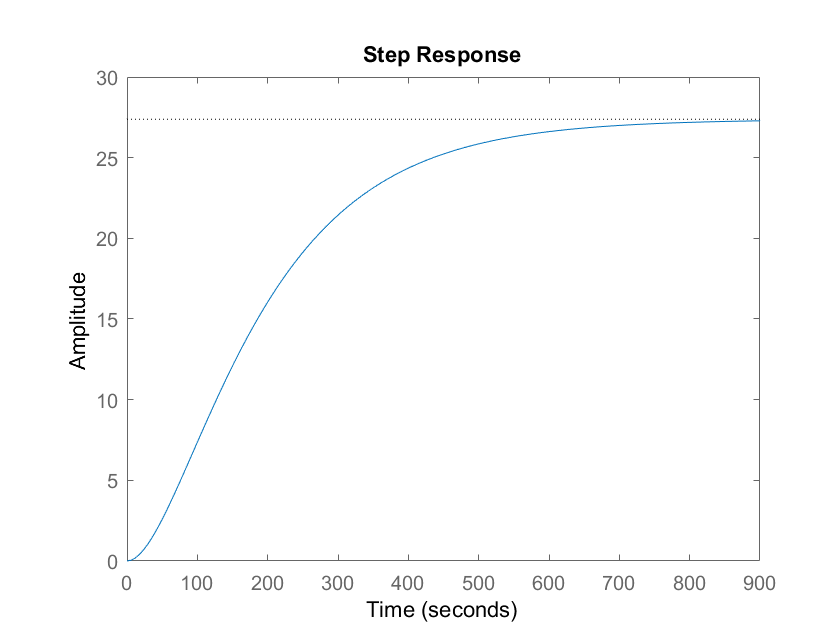

step(H2*u2)

Natural Frequency

H2N=tf([3.7/9206],[1 208.1/9206 1/9206])

H2N =
 
          0.0004019
  --------------------------
  s^2 + 0.0226 s + 0.0001086
 
Continuous-time transfer function.



wnH2=sqrt(0.0001086)

wnH2 = 0.0104

dH2=0.0226/(2*wnH2)

dH2 = 1.0843

settling time 

tssH2_2=(4/(dH2*wnH2))

tssH2_2 = 353.9823

tssH2_5=(3/(dH2*wnH2))

tssH2_5 = 265.4867